addpath('utils');
addpath('c:/myprograms/__github/SupervisedPCA/');

## Read data

%dataset = 'test_small_PCA'
dataset = 'train'

dataset = 'train'

load(['c:/Datas/DAPCA/MNIST_M/MNIST_',dataset,'.mat']);
X1 = data;
y1 = labels;
load(['c:/Datas/DAPCA/MNIST_M/MNIST_M_',dataset,'.mat']);
X2 = data;
y2 = labels;
disp(['X1 shape :',num2str(size(X1))])

X1 shape60000   2352


disp(['X2 shape :',num2str(size(X2))])

X2 shape59001   2352


X2c = 9001×2352 single matrix
    73    75    56    70    74    56    50    59    42    47    61    44    59    75    56    64    80    56    53    70    41    37    58    27    42    66    29    65    91    45    94   122    67   107   132    74   103   121    67   115   126    77   127   125    88   130   120    90   127   114
    48    56    37    62    77    51    74    91    60    66    83    51    71    84    53    87    94    64   102   103    76    94    84    63    79    64    50    65    53    42    45    42    28    61    65    45    82    91    65    75    85    53    86    98    65    74    88    54    67    82
    22    93   159    27    95   152    37    99   143    79   133   157   140   186   189   185   223   209   216   244   220   233   254   225   241   255   223   247   255   220   251   254   214   251   254   210   244   255   212   220   245   203   177   216   185   149   196   169   133   187
    66    46    40   125   118   113   130   129   124   129   128 

## Base PCA

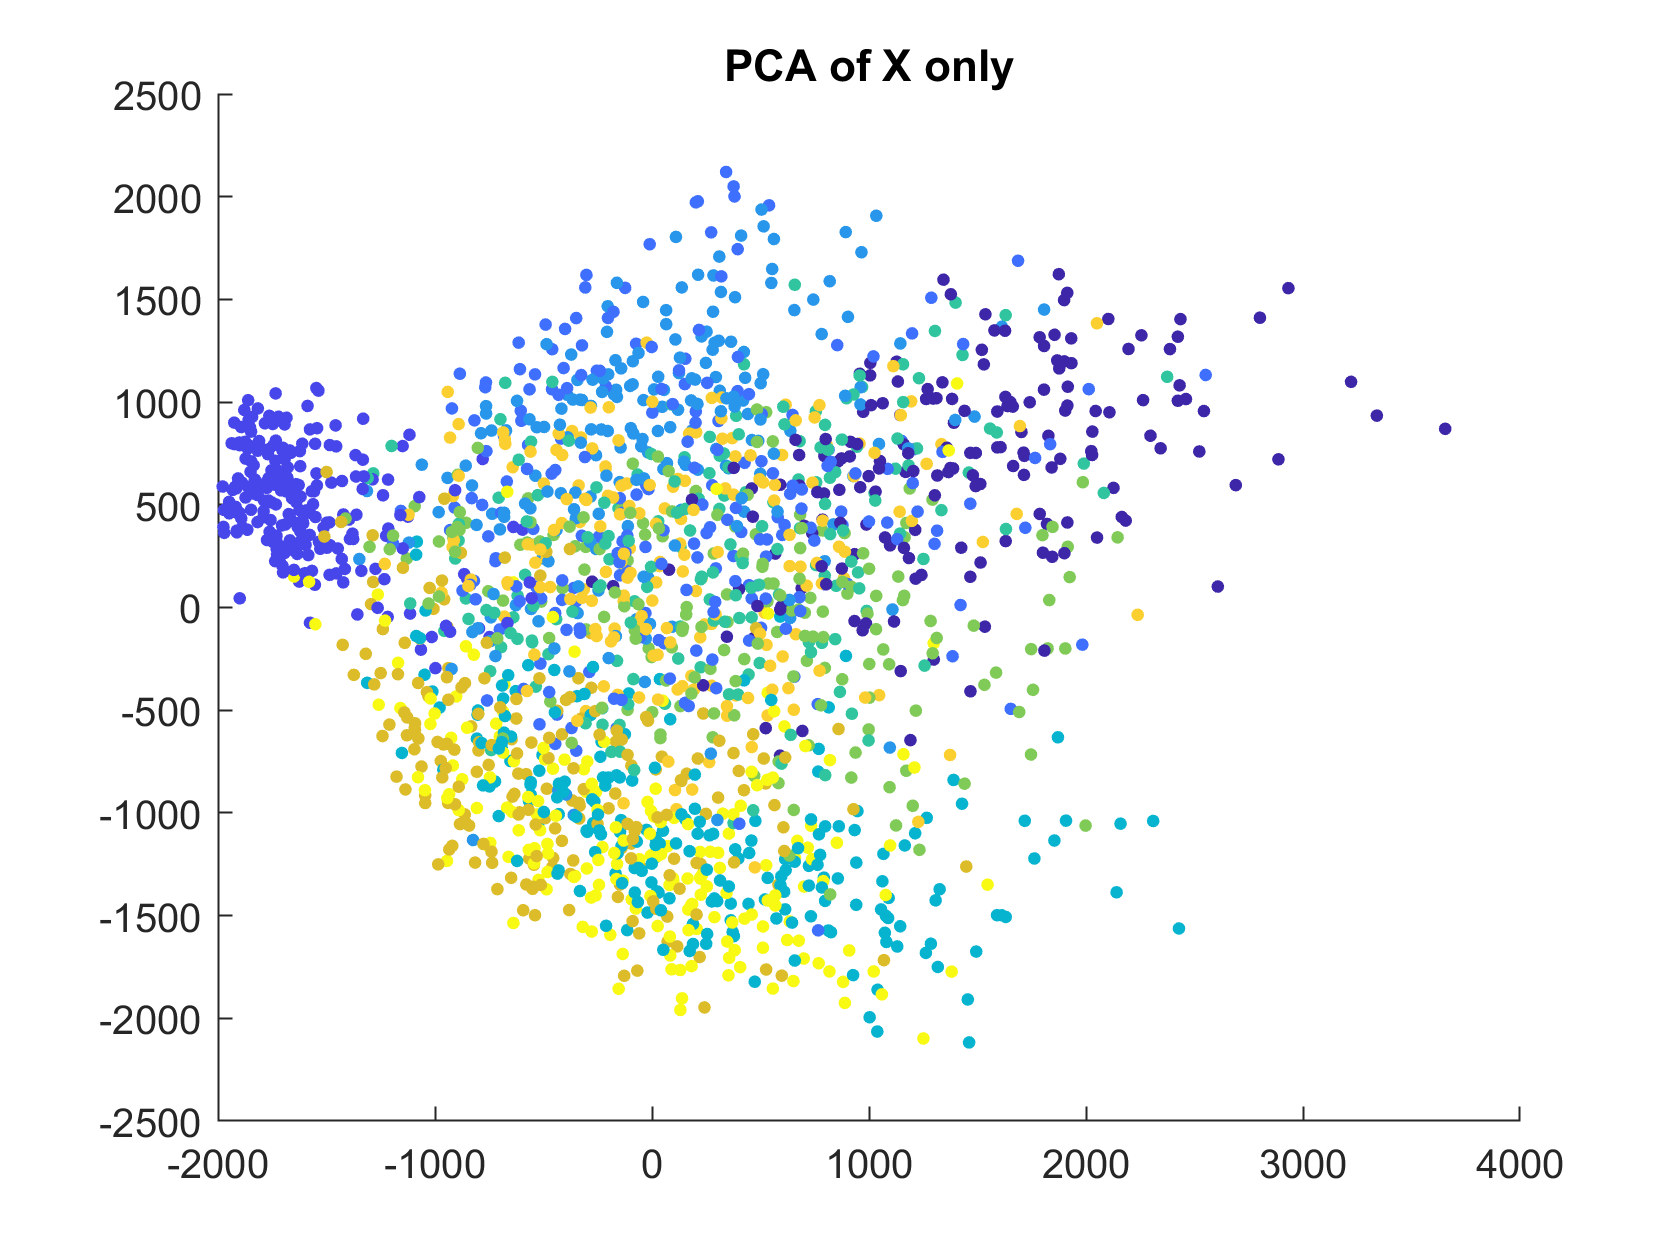

[v,u] = pca(X1);
scatter(u(:,1),u(:,2),10,y1,'filled'); title('PCA of X only');

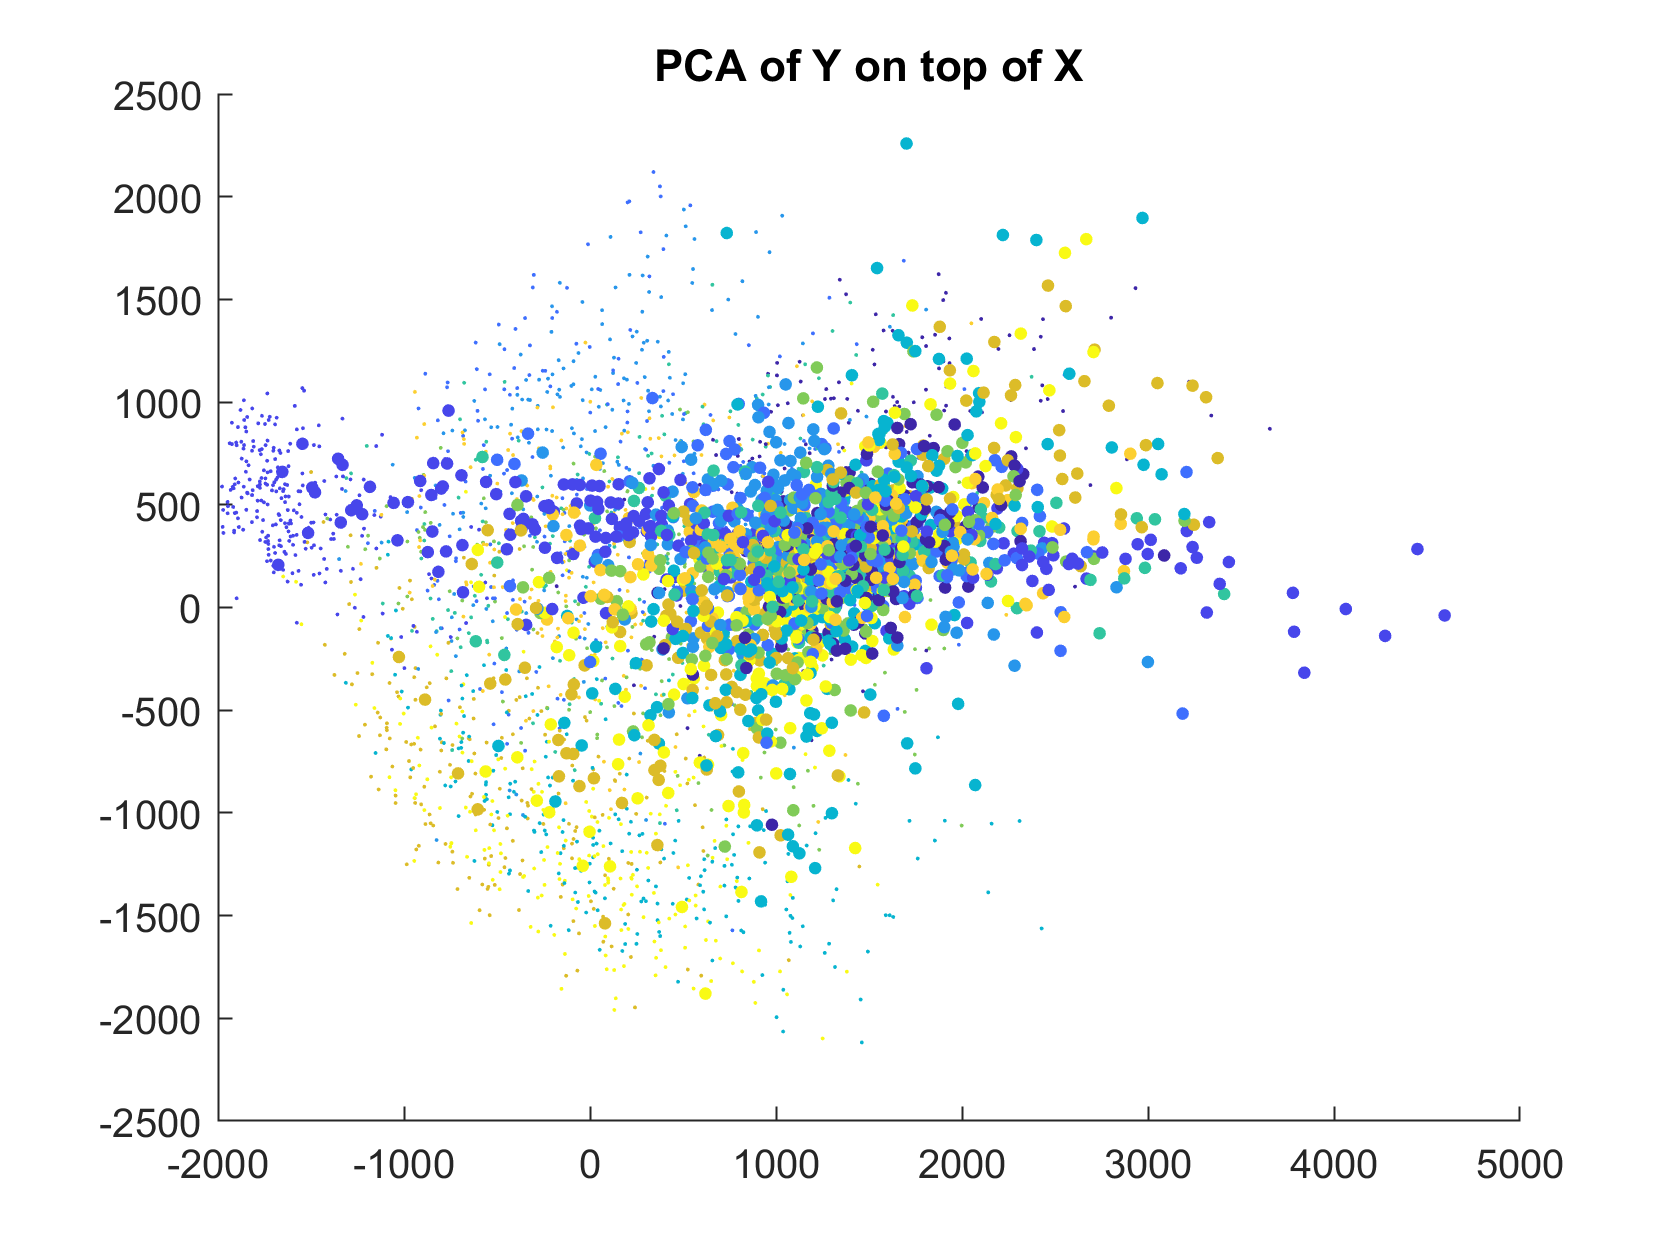

mn = mean(X1);
X2c = X2-mn;
u2 = X2c*v;
figure; 
scatter(u(:,1),u(:,2),1,y1,'filled'); 
hold on;
scatter(u2(:,1),u2(:,2),10,y2,'filled'); title('PCA of Y on top of X');

## SPCA through DAPCA

alpha = 1; 
% figure; [ V, D ] = SupervisedPCA(X1, y1, 2, alpha); u = X1*V; scatter(u(:,1),u(:,2),10,y1,'filled');
[V1, D1, PX, PY] = DAPCA(X1, y1, [], 2, 'alpha', alpha);

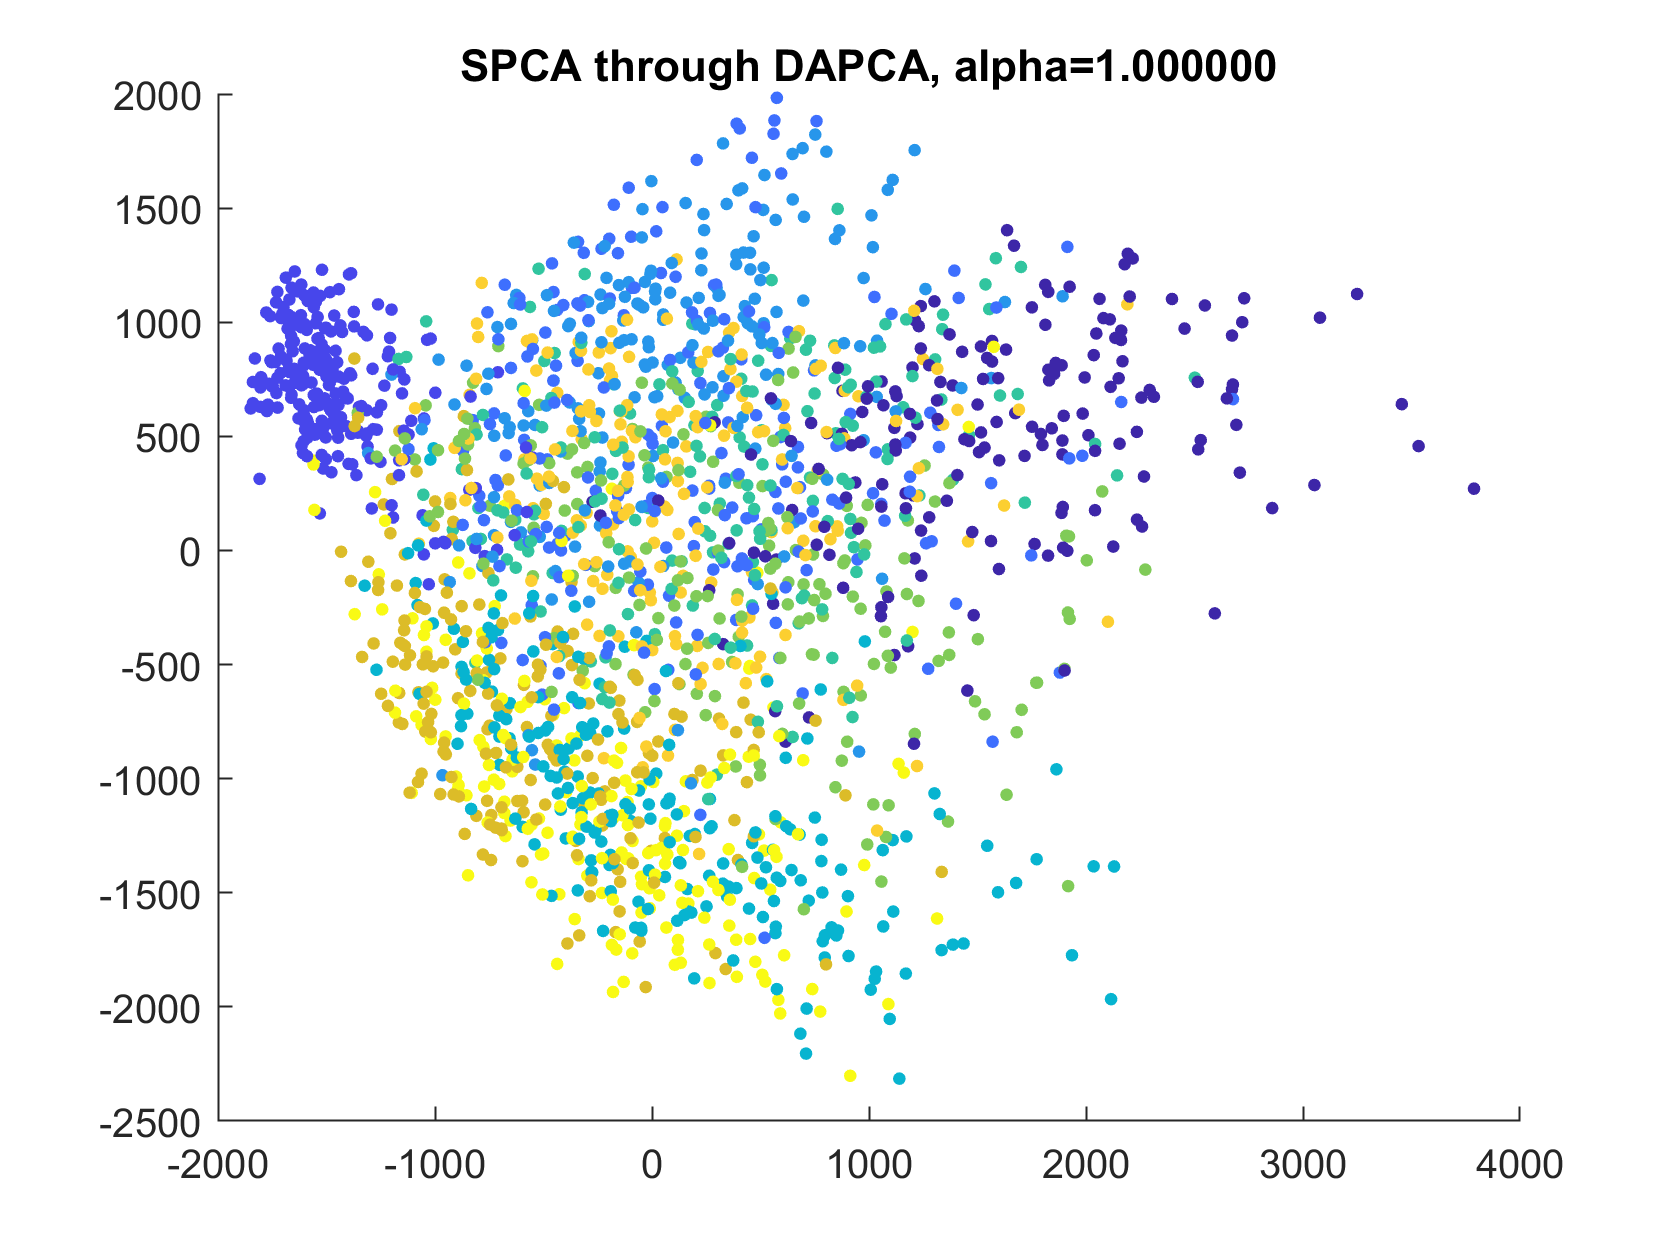

% Drawing
figure; 
scatter(PX(:,1), PX(:,2), 10, y1, 'filled'); 
title(sprintf('SPCA through DAPCA, alpha=%f', alpha));
saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f.png', alpha));

## Save fragments and PCA projections (on X)

nsamples = 5000

nsamples = 5000

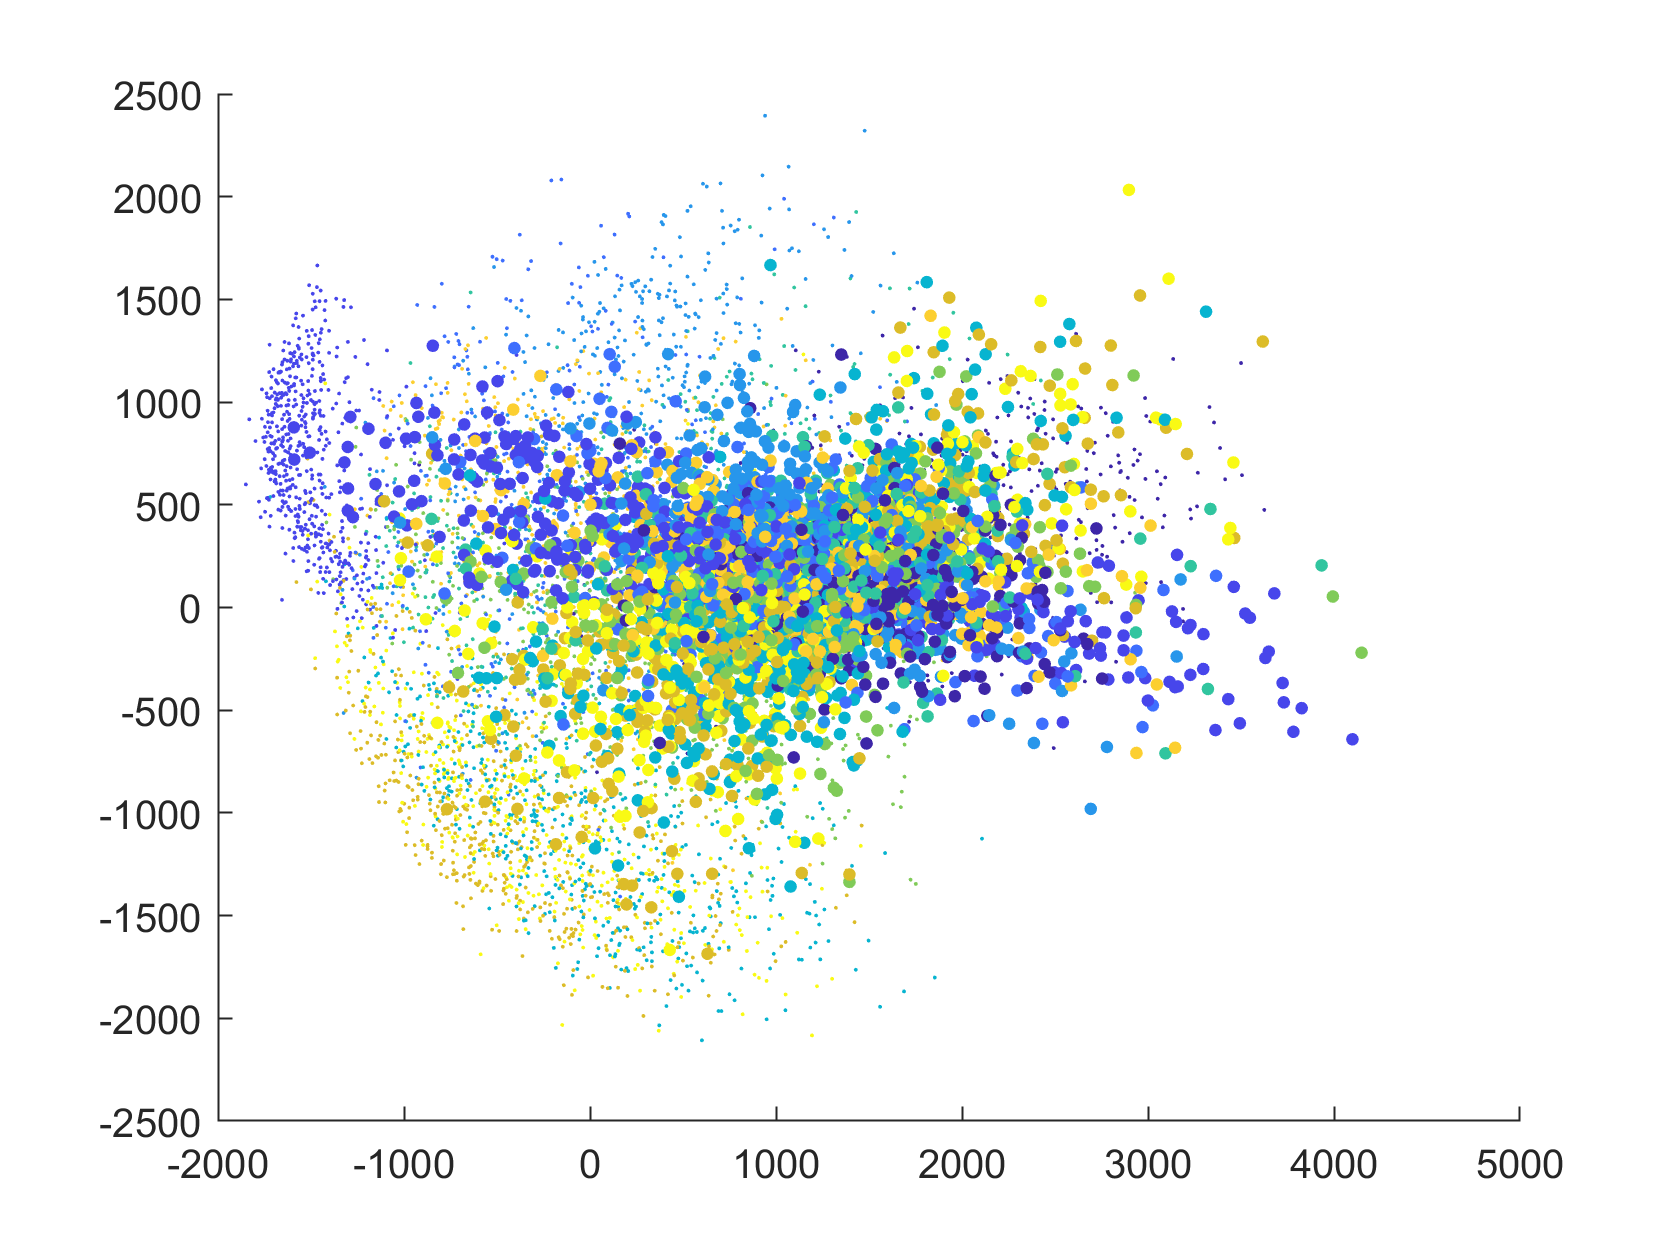



data = X1(1:nsamples,:);
labels = y1(1:nsamples);
save(['datasets/MNIST_M/MNIST_',dataset,'_small.mat'],'data','labels')
data = X2(1:nsamples,:);
labels = y2(1:nsamples);
save(['datasets/MNIST_M/MNIST_M_',dataset,'_small.mat'],'data','labels')

[v,u] = pca(X1(1:nsamples,:),'NumComponents',50);
mn = mean(X1(1:nsamples,:));
X2c = X2(1:nsamples,:)-mn;
u2 = X2c*v;
scatter(u(:,1),u(:,2),1,y1(1:nsamples),'filled'); 
hold on;
scatter(u2(:,1),u2(:,2),10,y2(1:nsamples),'filled'); 

data = u;
labels = y1(1:nsamples)

labels = 1×5000 int64 row vector
   5   0   4   1   9   2   1   3   1   4   3   5   3   6   1   7   2   8   6   9   4   0   9   1   1   2   4   3   2   7   3   8   6   9   0   5   6   0   7   6   1   8   7   9   3   9   8   5   9   3


save(['datasets/MNIST_M/MNIST_',dataset,'_small_PCA.mat'],'data','labels')
data = u2;
labels = y2(1:nsamples)

labels =      5     0     4     1     9     2     1     3     1     4     3     5     3     6     1     7     2     8     6     9     4     0     9     1     1     2     4     3     2     7     3     8     6     9     0     5     6     0     7     6     1     8     7     9     3     9     8     5     9     3


save(['datasets/MNIST_M/MNIST_M_',dataset,'_small_PCA.mat'],'data','labels')


alpha = 5;
beta = 1;
gamma = 0.02;
% delta = [1,2,3,4,1,2,3,4,1,2];
tic;
[V2, D2, PXd, PYd] = DAPCA(X1, y1, X2, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma,'kNN',10);

Matrix dimensions must agree.

Error in DAPCA (line 407)
        Q1 = X' * (wXX .* X);

toc;
disp(D2)
% Drawing
figure; 
scatter(PXd(:,1),PXd(:,2),10,y1,'filled'); title('Result of DAPCA')
% title(sprintf('SPCA through DAPCA, alpha=%4.2f, delta = [%4.2f,%4.2f,%4.2f]', alpha, delta));
% saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f_delta_[%4.2f,%4.2f,%4.2f].png', alpha, delta));

## Figure with Y for comparison

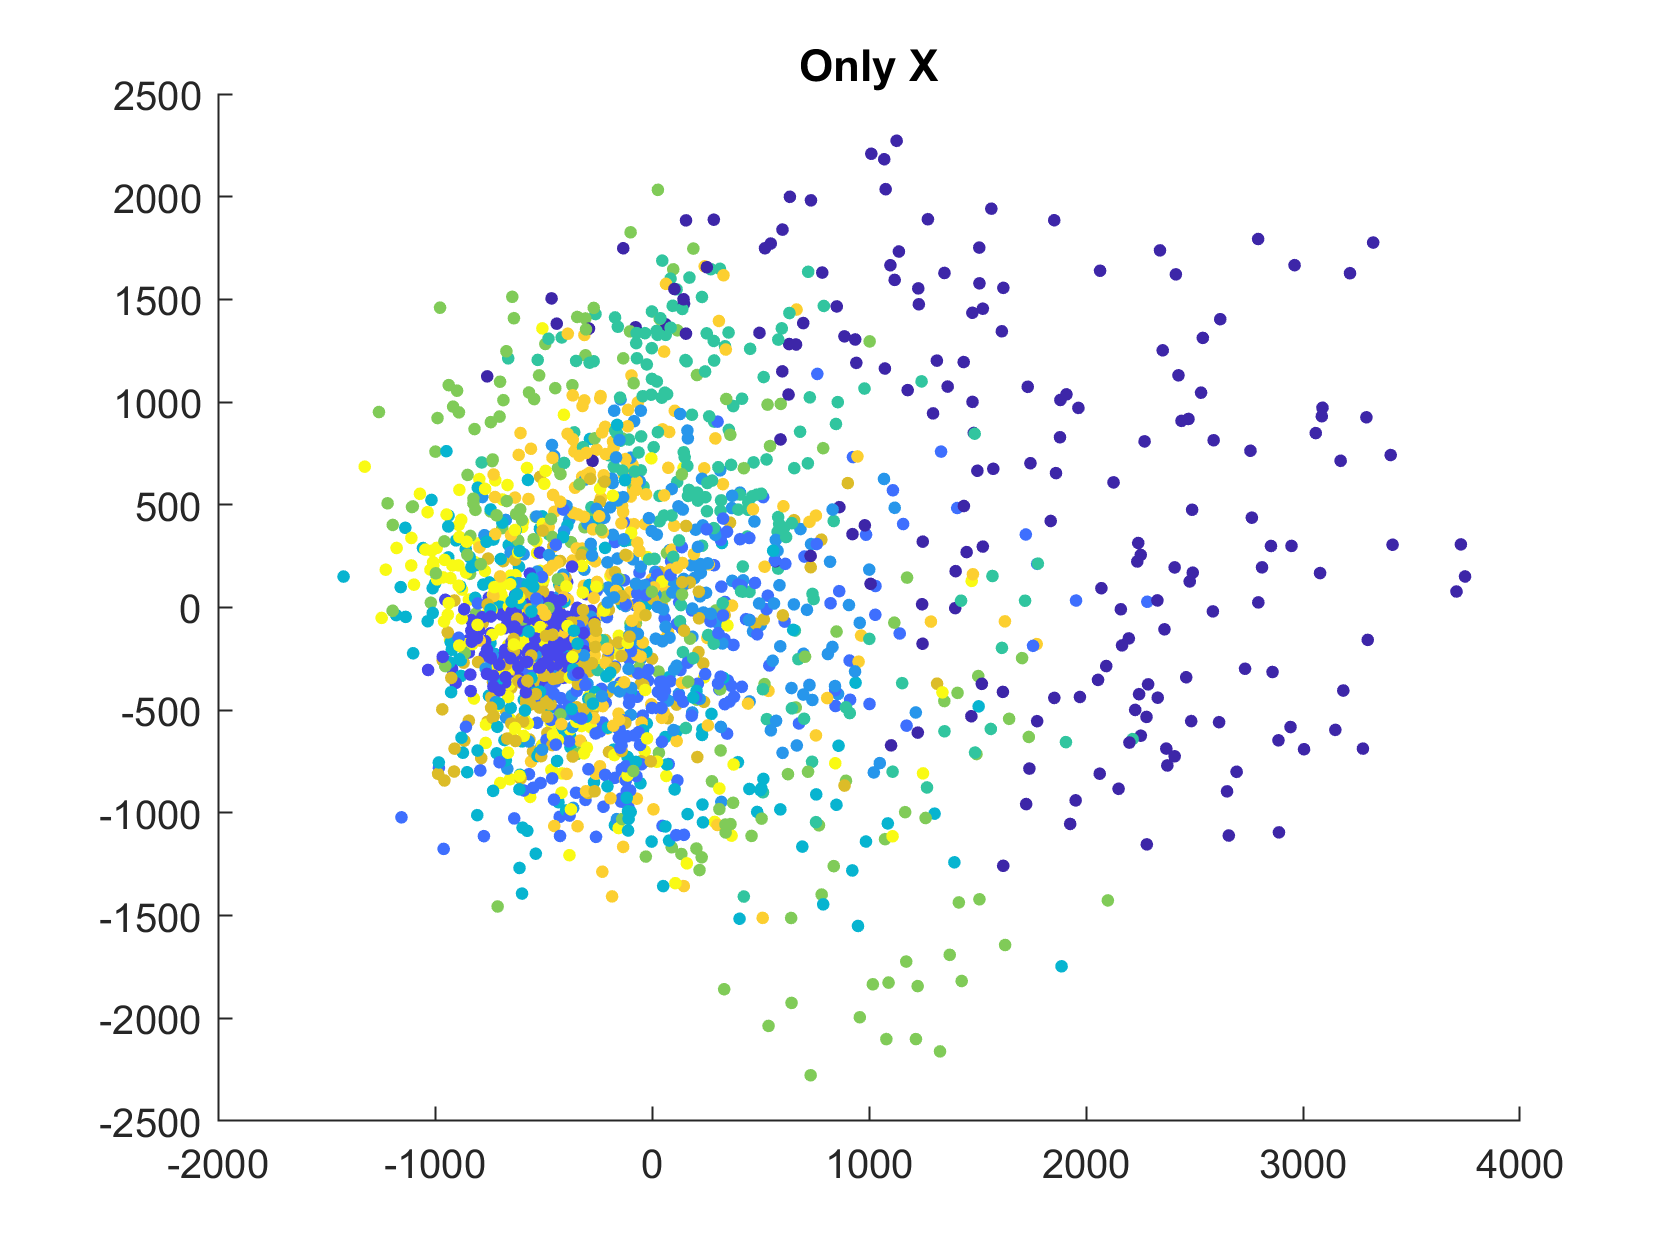


PY = X2 * V2;
figure; 
scatter(PXd(:,1), PXd(:,2), 10, y1, 'filled'); title('Only X');

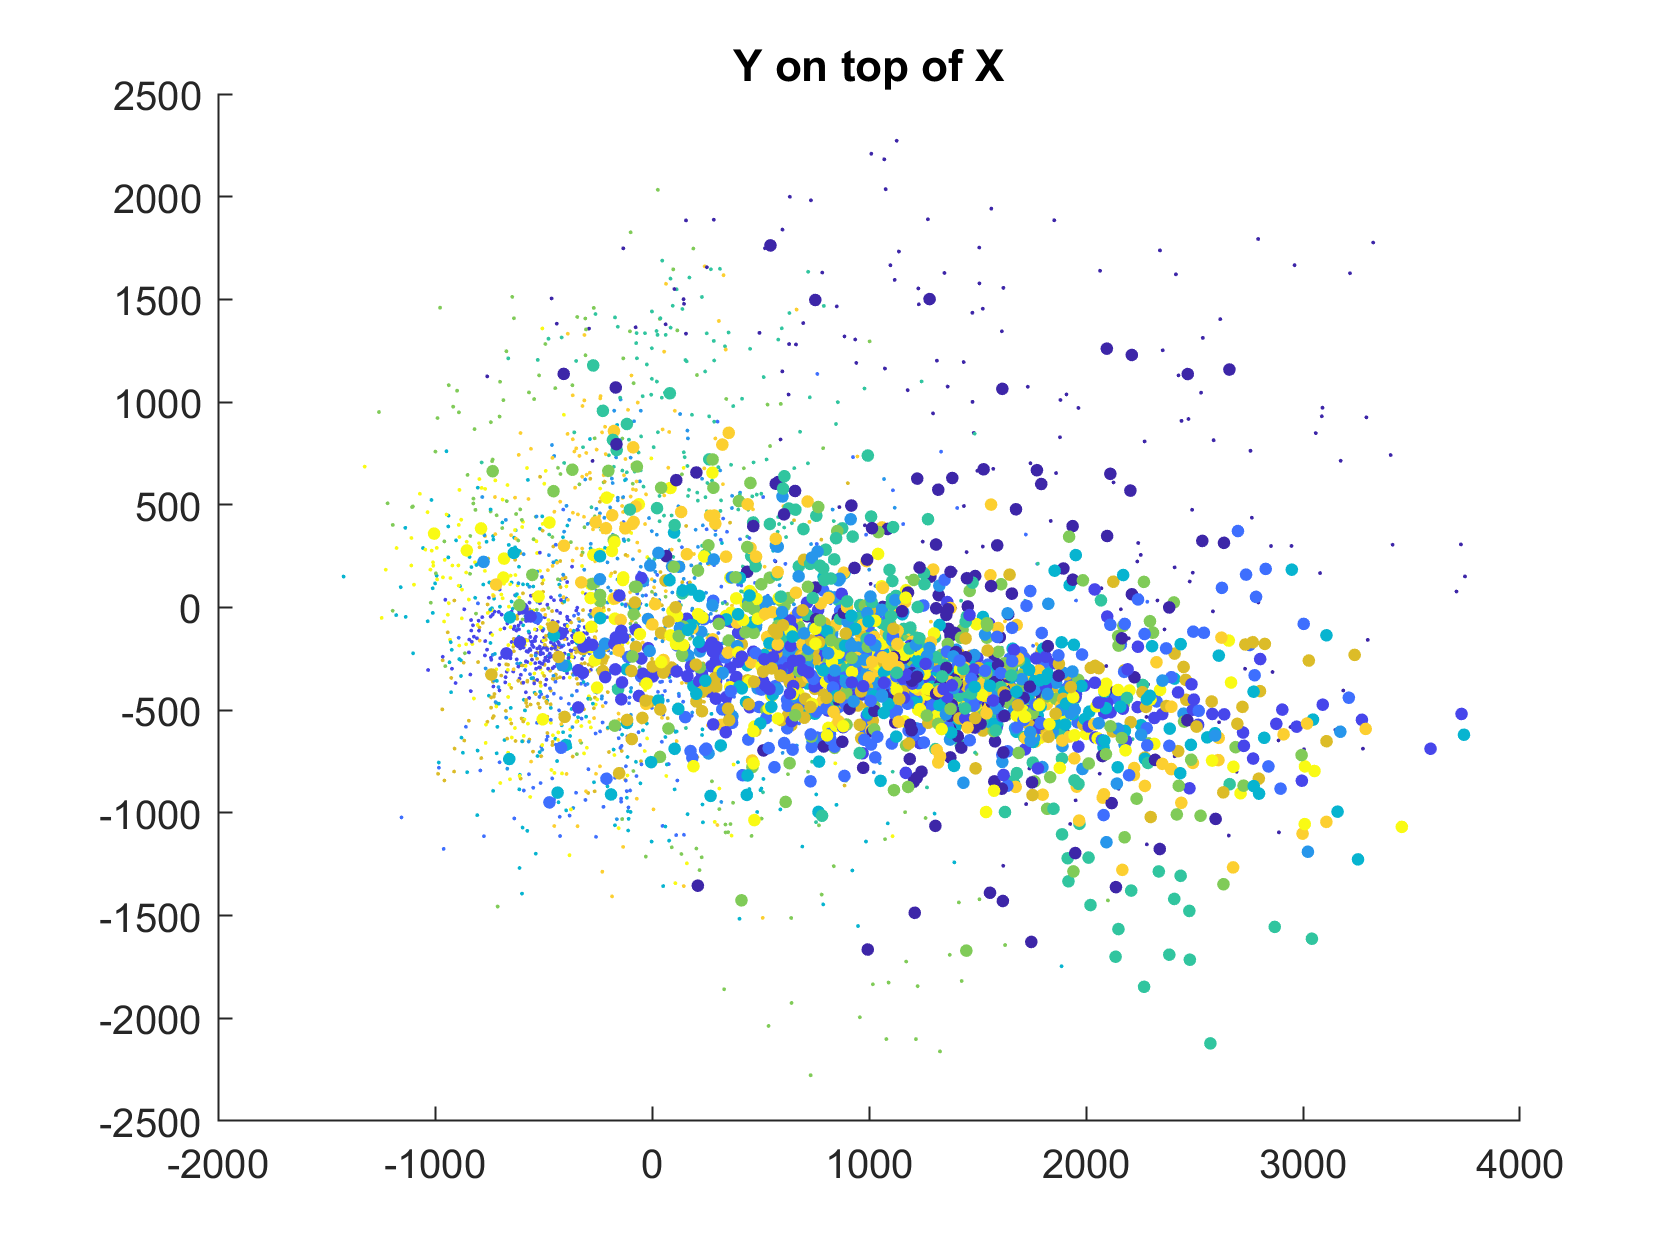

figure;
scatter(PXd(:,1), PXd(:,2), 1, y1, 'filled'); title('Y on top of X');
hold on;
scatter(PY(:,1),PY(:,2),10,y2,'filled'); 

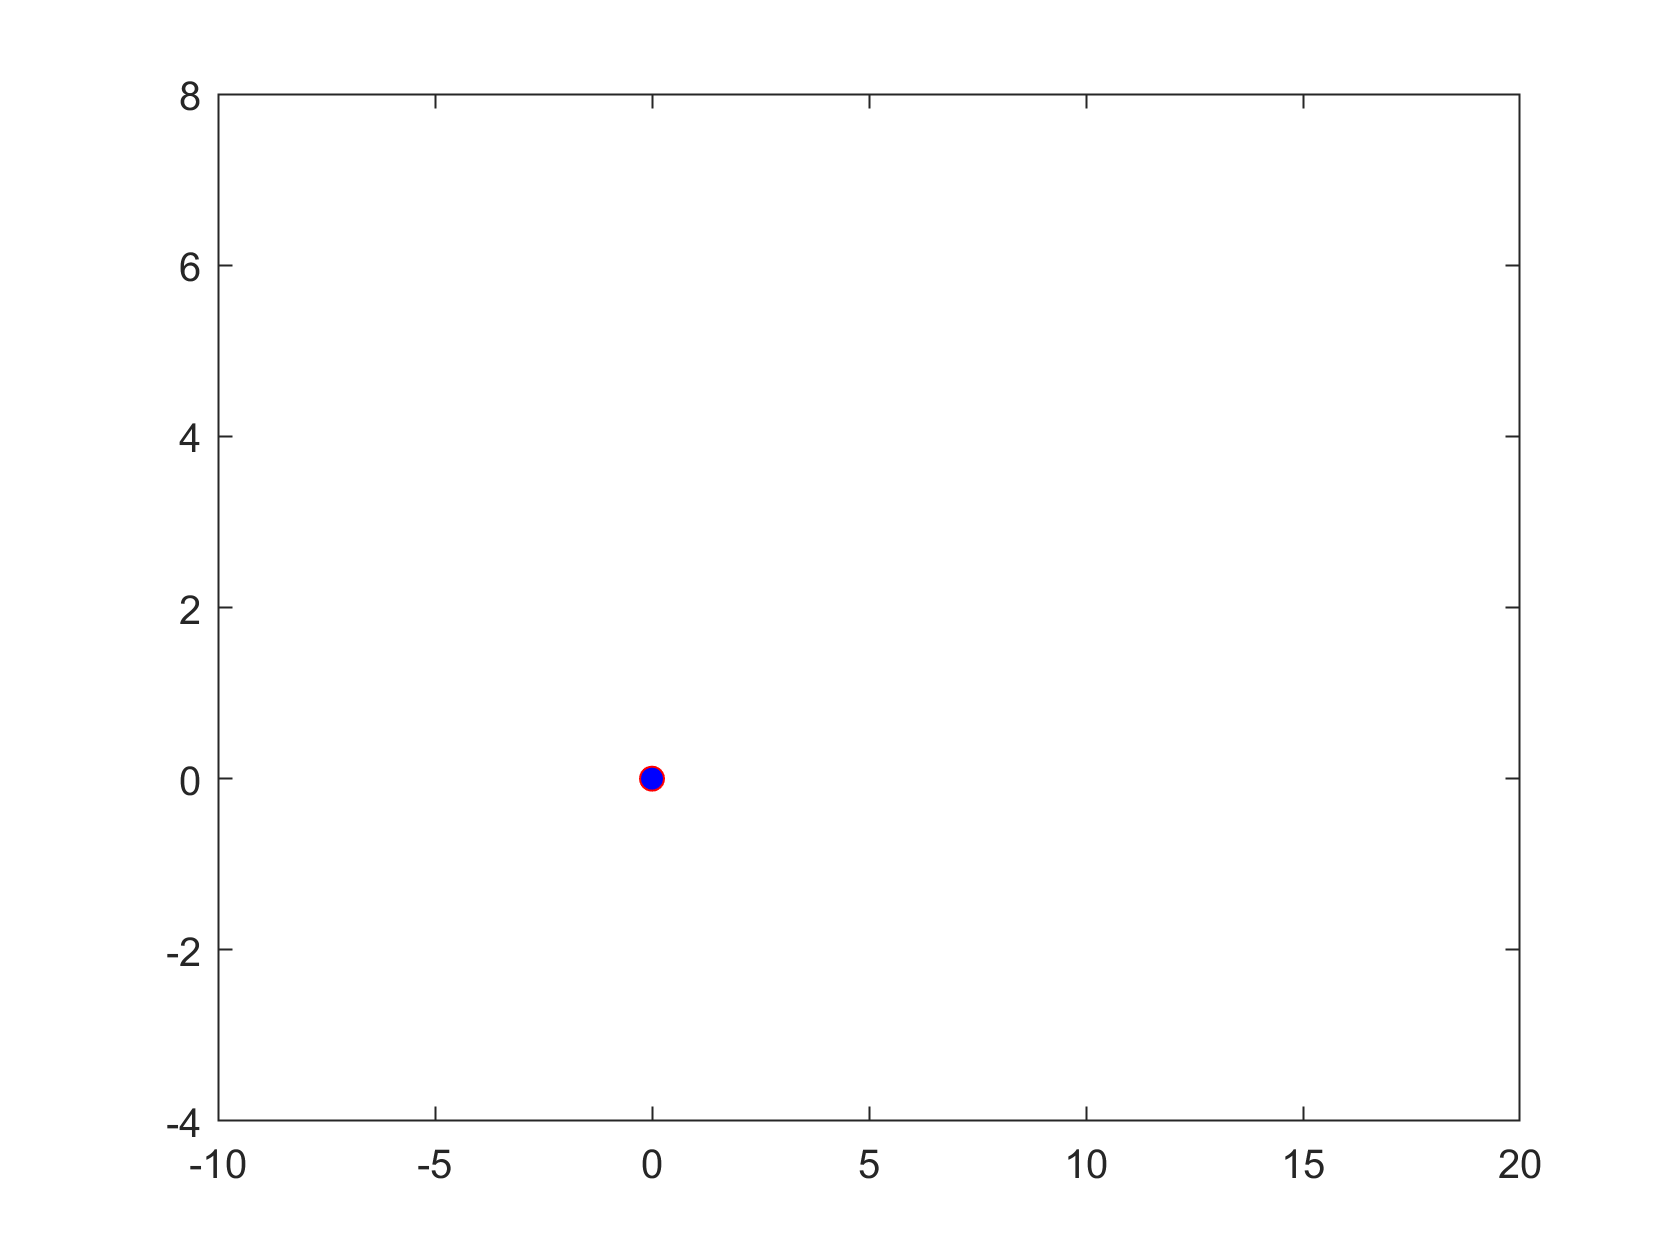

%title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
%saveFigures(sprintf('Figures\\DAPCA Y without Y in search, alpha %4.2f.png', alpha));
% Draw centroids
figure
mi = mean(PX);
plot(mi(1),mi(2),'or','markerfacecolor', 'b');
hold on;
mi = mean(PY);
plot(mi(1),mi(2),'or','markerfacecolor', 'r');
xlim([-10, 20]);
ylim([-4, 8]);
saveFigures(sprintf('Figures\\Centroids DAPCA Y without Y in search, alpha %4.2f.png', alpha));

## Redraw for shifted Y

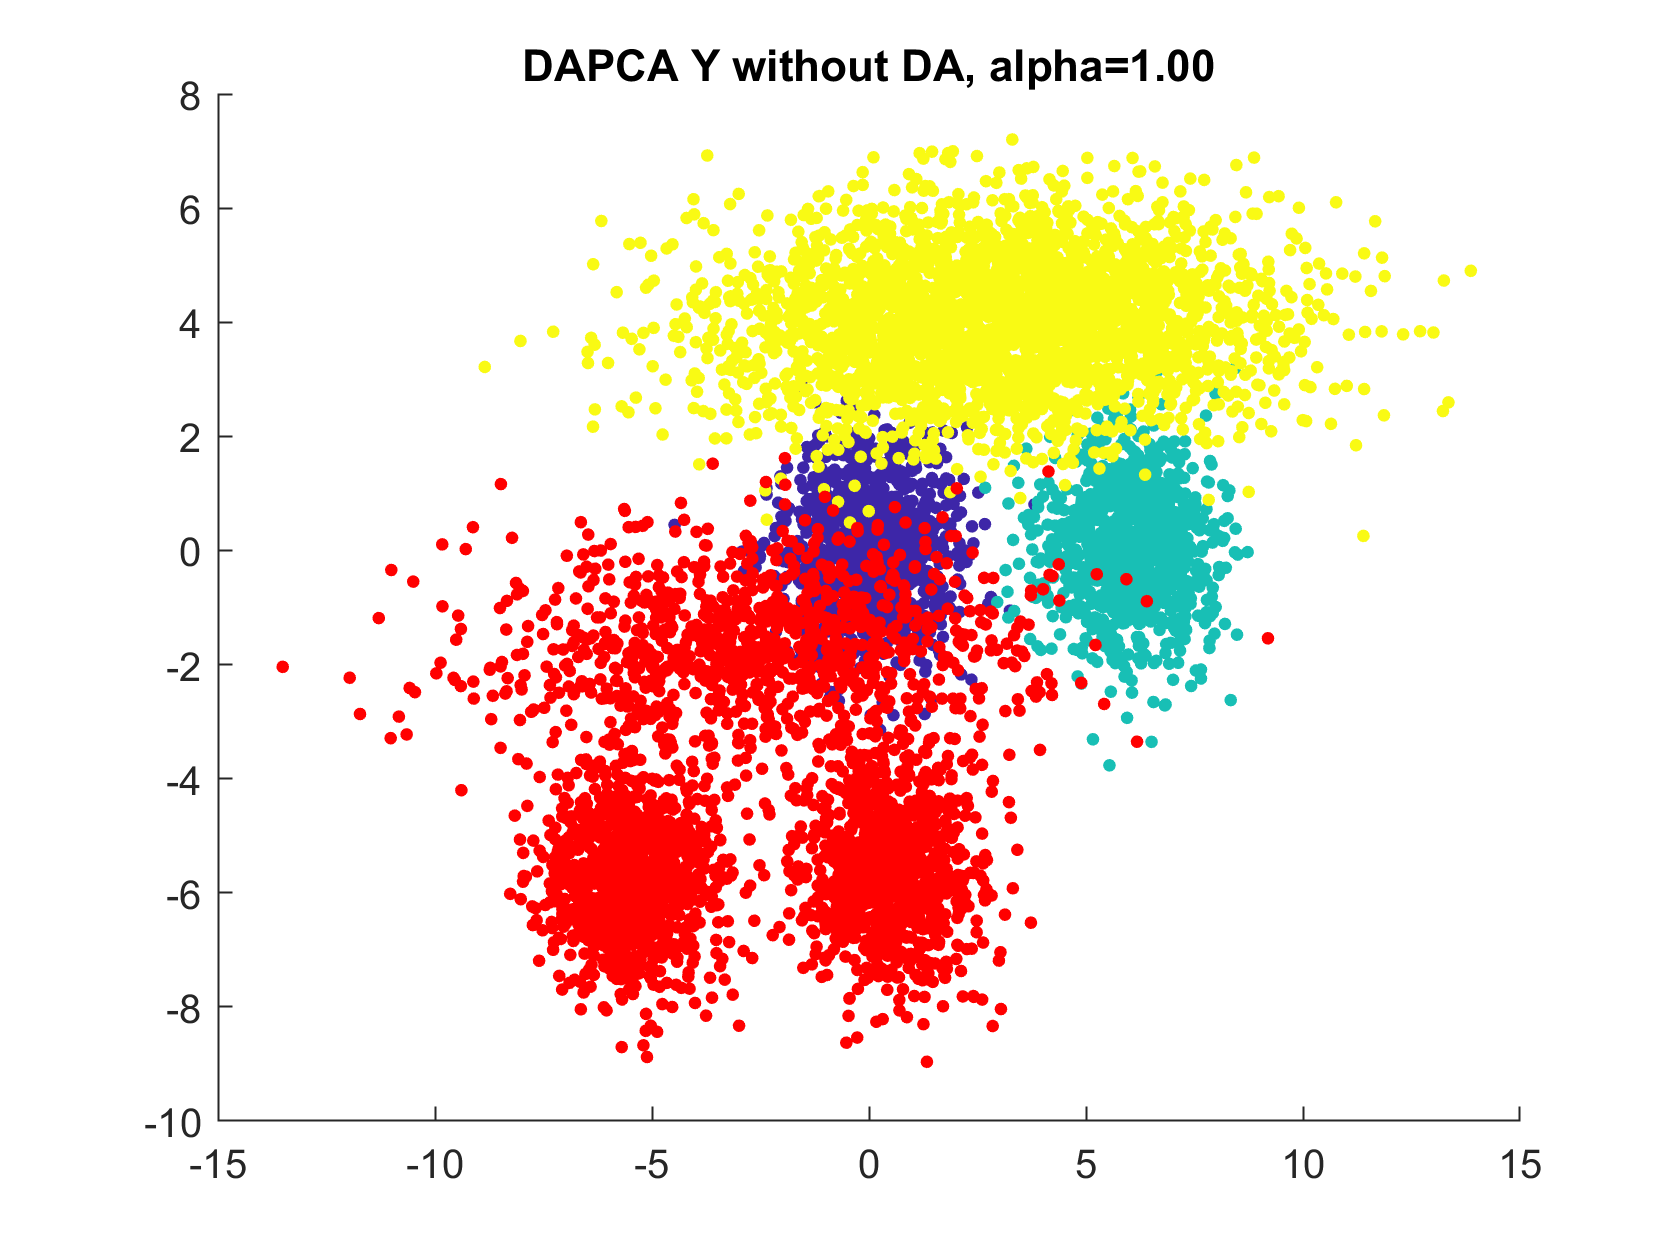

PY = (Y - 5) * V1;
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
saveFigures(sprintf('Figures\\DAPCA SY without Y in search, alpha %4.2f.png', alpha));

## Repulsion in Y

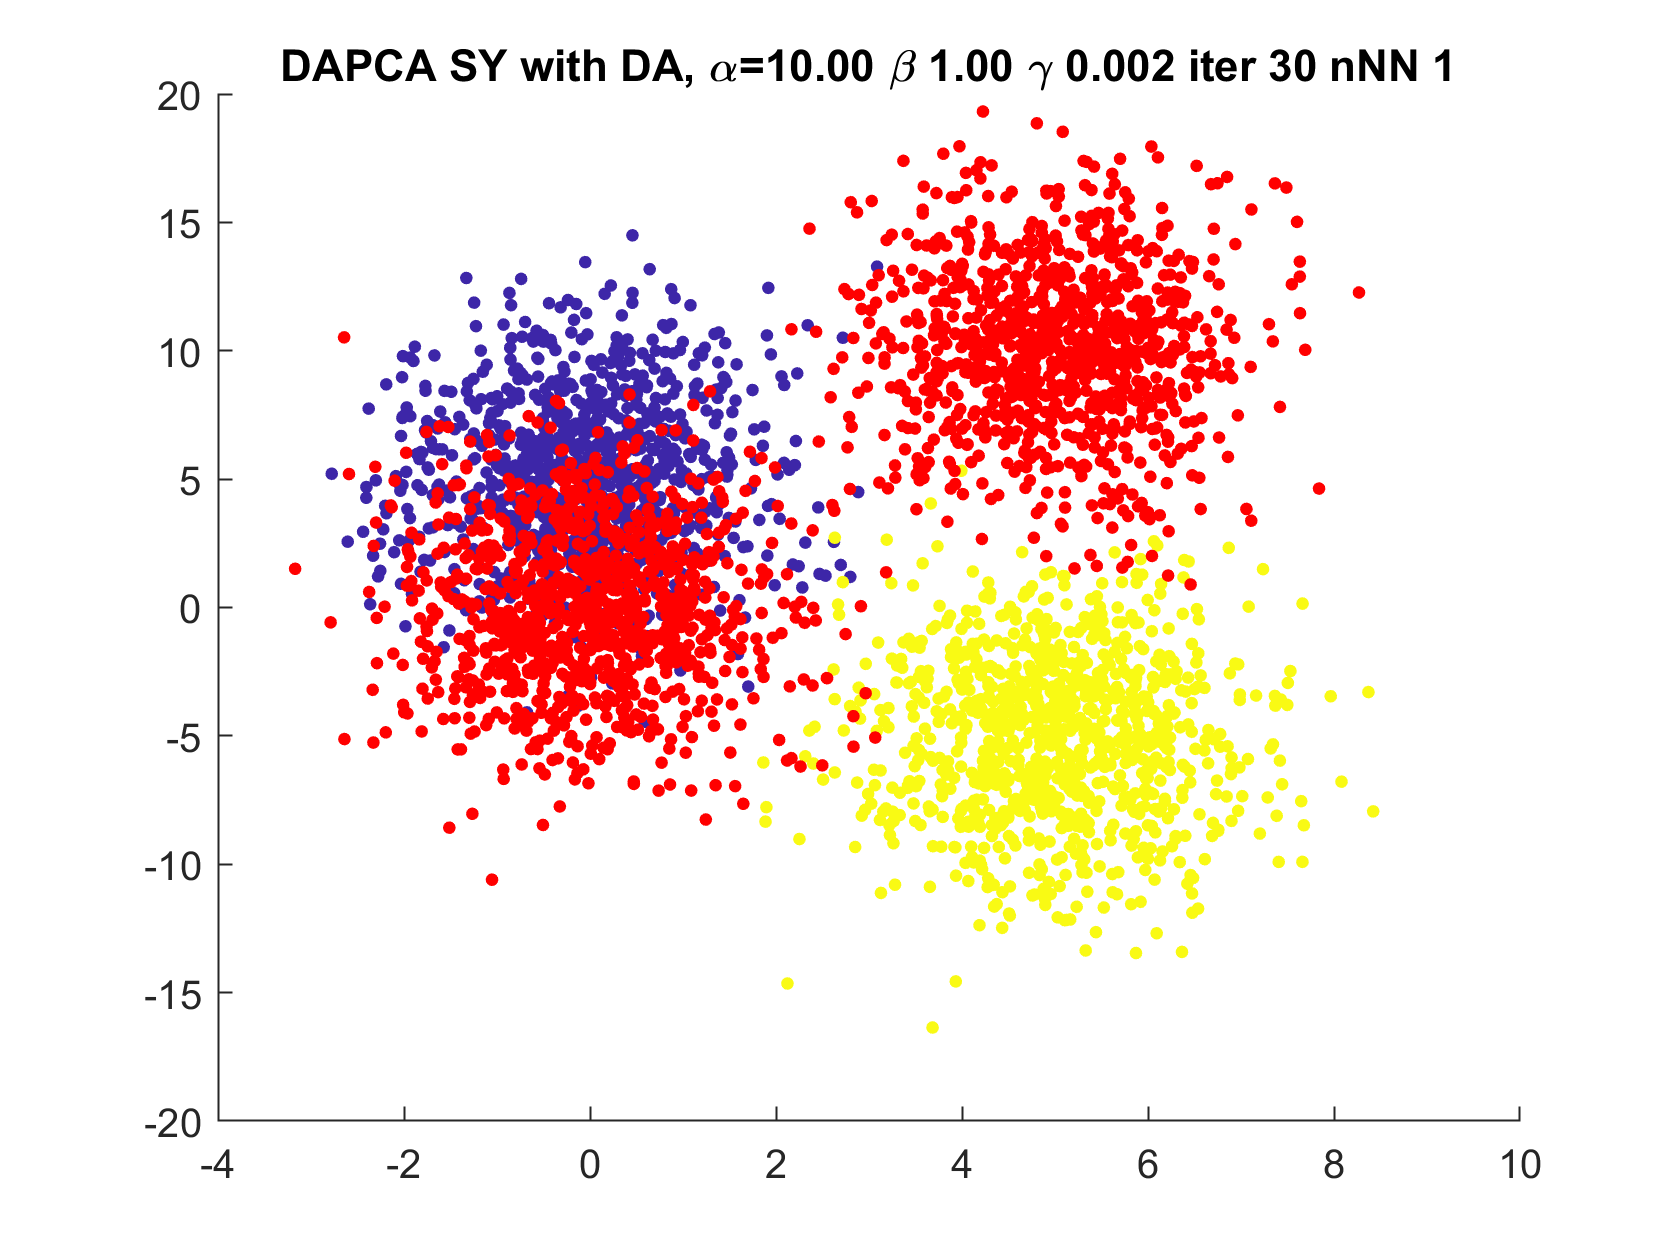

beta = 1;
delta = 1;
alpha = 10;
gamma = 0.0015;
maxIter = 30;
SY = Y;
kNN = 1;
[V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
% Draw
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA SY with DA, \\alpha=%4.2f \\beta %4.2f \\gamma %5.3f iter %d nNN %d', alpha, beta, gamma, maxIter, kNN));
saveFigures(sprintf('Figures\\DAPCA Y with DA, alpha %4.2f beta %4.2f gamma %5.3f iter %d nNN %d.png', alpha, beta, gamma, maxIter, kNN));

## Recalculation for three steps

PC1 = [];
PC2 = [];
meanDist = [];
for maxIter = 1:3
    [V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
    PC1 = [PC1, V(:, 1)];
    PC2 = [PC2, V(:, 2)];
    meanDist = [meanDist, sum((mean(PX) - mean(PY)) .^ 2)];
    disp(meanDist)
end

    6.5695

    6.5695    6.5796

    6.5695    6.5796    6.5798



Angles calculation

tmp = PC1' * PC1;
tmp(tmp > 1) = 1;
PC1a = acosd(tmp);
tmp = PC2' * PC2;
tmp(tmp > 1) = 1;
PC2a = acosd(tmp);

## Comparison of V with the first elements of PC1 and PC2

ang1 = acosd(V(:, 1)' * PC1(:, 1));
ang2 = acosd(V(:, 2)' * PC2(:, 1));
mDist = sum((mean(PX) - mean(PY)) .^ 2);